%% Examples using Evaluate_Masks function

% without any parameter. This means Pause_Period = 0 and evaluates the
% masks stored in the directories selected by user interactivelly.
Evaluate_Masks

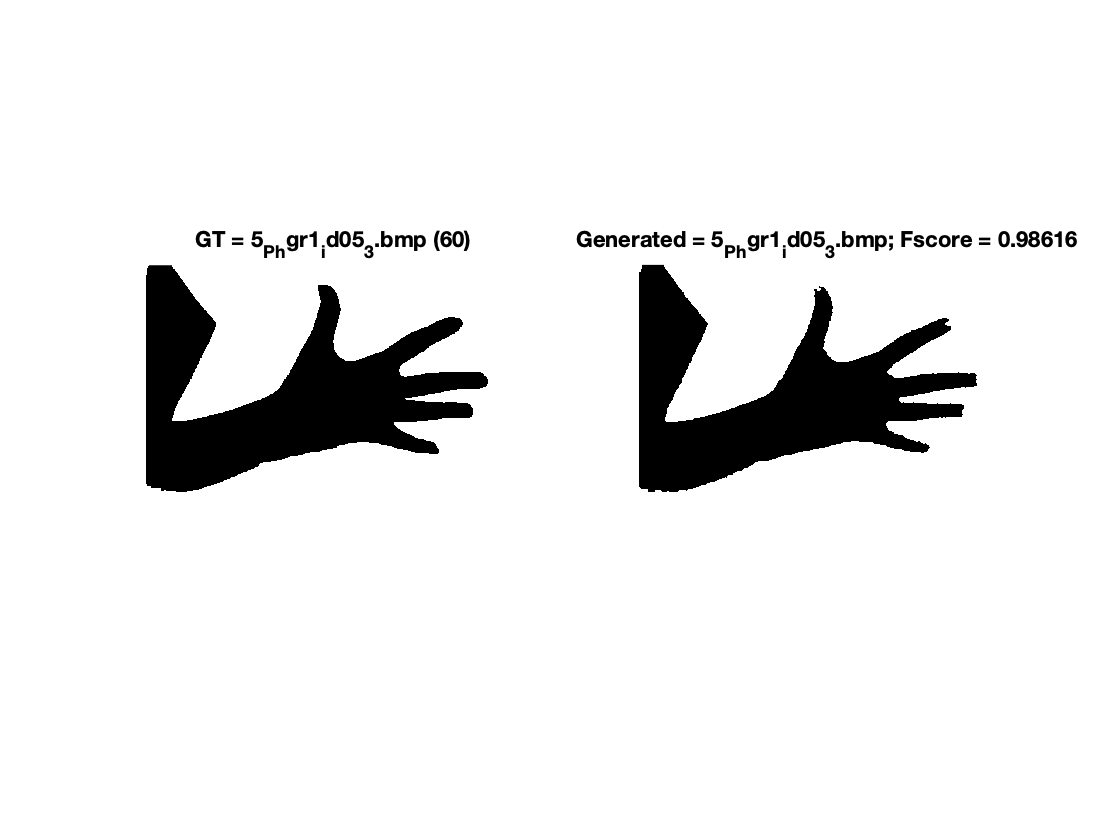

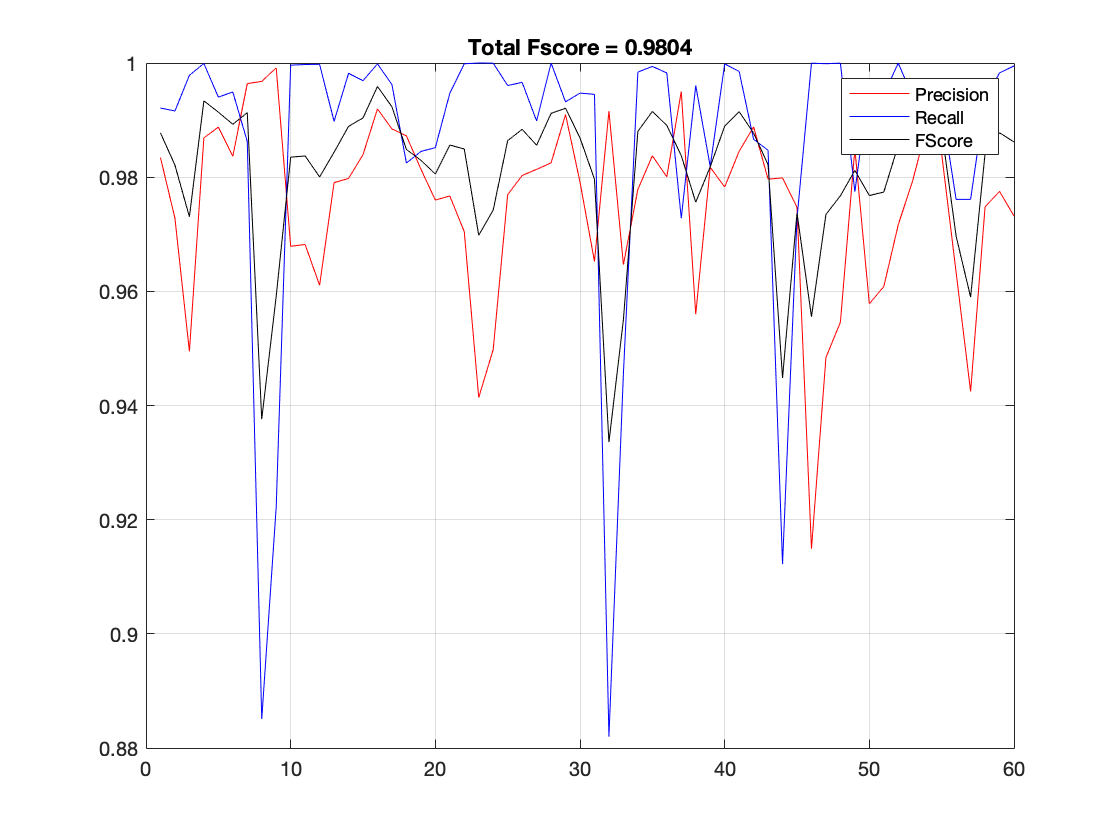

Mean Fscore = 0.9804


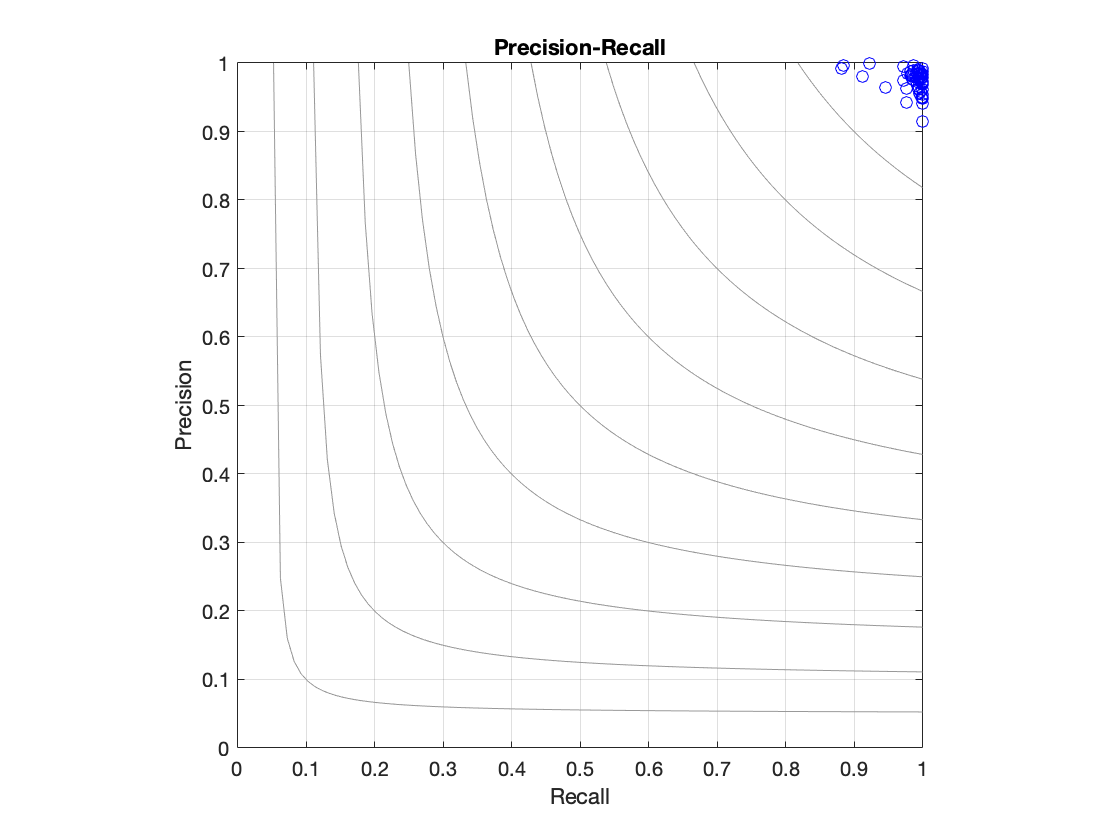

%% Alternativelly you can specify Pause_period and the directories:


[Pre,Rec,FScore]=Evaluate_Masks(0, './Training-Dataset/Masks-Ideal/', './Training-Dataset/Masks/');

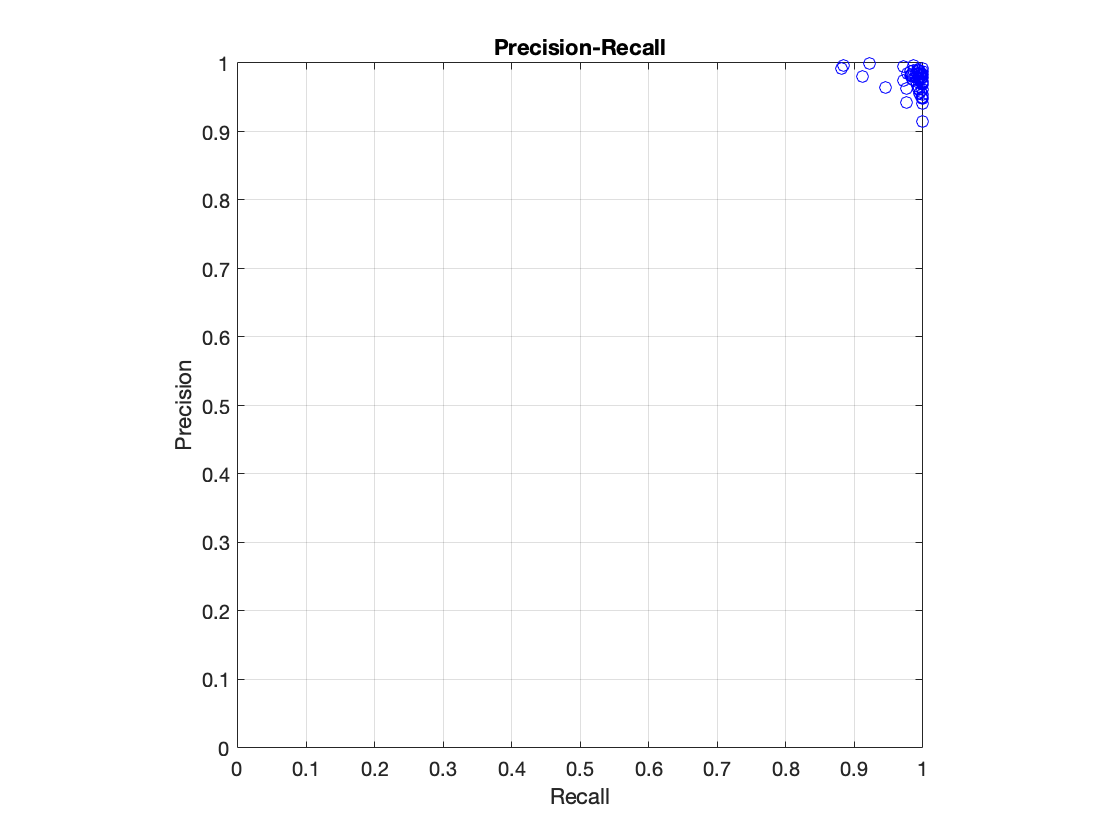


figure(4)
plot(Rec,Pre,'ob');
grid
title('Precision-Recall');
ylabel('Precision')
xlabel('Recall')
axis equal
axis([0 1 0 1])

% Labeling results below Fvalue
Fvalue = 0.8;
hold on
for i=1:length(Pre)
    if (FScore(i)<Fvalue)
        text(Rec(i)+0.01,Pre(i)-0.01,num2str(i));
    end
end
hold off

%% Alternativelly can be used to evaluate the binarization system with Validation-Dataset
Evaluate_Masks(0, './Validation-Dataset/Masks-Ideal/', './Validation-Dataset/Masks/');